irr_vs_fir: script to compare IIR and FIR filters dimensions for similar frequency response.

Version: 001

Date:    2020/04/21

Author:  Rodrigo Gonzalez <rodralez@frm.utn.edu.ar>

URL:     https://github.com/rodralez/td3

URL:     https://github.com/rodralez/control

clc
clear
close all

## FIR

% fir_kaiser_3400_44100: Low-pass FIR filter, Kaiser window.

Hd_fir = fir_kaiser_3400_44100;

fir_coeff = Hd_fir.coefficients;

## IIR

% iir_elliptic_3400_44100: funcion que disena un filtro IIR a partir de
% filtro analogico eliptico

Hd_iir = iir_elliptic_3400_44100;

iir_coeff = Hd_iir.coefficients;

## PLOT

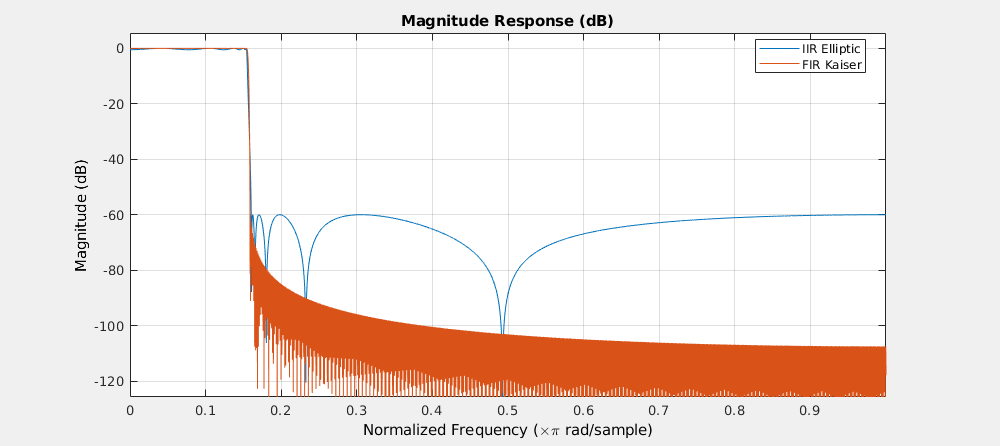

% fvtool: filter visualization tool

hfvt = fvtool(Hd_iir, Hd_fir, 'Analysis','Magnitude');
legend(hfvt,'IIR Elliptic', 'FIR Kaiser')

## Filters dimensions

fir_dim = size(Hd_fir.Numerator)

fir_dim =           1.00       1600.00



iir_dim = size(Hd_iir.sosMatrix)

iir_dim =           5.00          6.00
